# Obstacle-Free Path Planning Using Hybrid A Star

Plan a collision-free path for a vehicle through a parking lot by using the Hybrid A* algorithm.

## Create and Assign Map to State Validator

Load the cost values of cells in the vehicle costmap of a parking lot.

load map_straight_with_roundabout_invertita.mat % costVal

Create a [`binaryOccupancyMap`](docid:nav_ref#bunq527) with cost values.

resolution = 3;
map = binaryOccupancyMap(map_straight_with_roundabout_invertita,resolution);

Create a state space.

ss = stateSpaceSE2;

Update state space bounds to be the same as map limits.

ss.StateBounds = [map.XWorldLimits;map.YWorldLimits;[-pi pi]];

Create a state validator object for collision checking.

sv = validatorOccupancyMap(ss);

Assign the map to the state validator object.

sv.Map = map;

## Plan and Visualize Path

Initialize the [`plannerHybridAStar`](docid:nav_ref#object_plannerhybridastar) object with the state validator object. Specify the `MinTurningRadius` and `MotionPrimitiveLength` properties of the planner.

planner = plannerHybridAStar(sv, ...
                             MinTurningRadius=4, ...
                             MotionPrimitiveLength=6);

Define start and goal poses for the vehicle as [*x, y, theta*] vectors. *x* and *y* specify the position in meters, and *theta* specifies the orientation angle in radians.

startPose = [0 27 pi/2]; % [meters, meters, radians]
goalPose = [130 27 -pi/2];

Plan a path from the start pose to the goal pose.

refpath = plan(planner,startPose,goalPose,SearchMode='exhaustive');     

Visualize the path using show function.

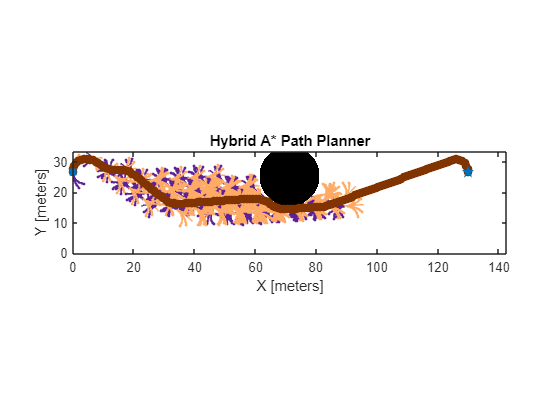

show(planner)

*Copyright 2019 The MathWorks, Inc.*